% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), filesep);
idx = find(strcmp(file_path, 'uavtestbed'));
root_directory = strjoin(file_path(1:idx), filesep);
% switch to the root directory
cd(root_directory);

tarot_id = 32;

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% load distance matrix
H = load('distance_matrix.mat').H;
% load the api
api = jsondecode(fileread('sql/api.json'));

% username=input('username: ', 's');
% password=input('password: ', 's');
username = 'macslab';
password = 'Ch0colate!';
db_name = 'uav2_db';
%the database connection
% conn = postgresql(username, password, "Server", 'localhost', "PortNumber", 5432, "DatabaseName", 'uav2_db');
conn = database(db_name, username, password);

% check out what UAVs are in the db
uav_tb = select(conn, api.matlab.assets.LOAD_ALL_UAVS)

uav_tb = 102×20 table
     age      serial_number       common_name       id     version    airframe_id    battery_id                motors_id                             escs_id                 m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    gps_id    max_flight_time    dynamics_srate
    ______    _____________    _________________    ___    _______    ___________    __________    _________________________________    _________________________________    _____ 

row = 2;
uav = uav_tb(row,:);
uav = load_uav_id(conn, api, uav)

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
               escs: [8×1 struct]
             motors: [8×1 struct]
                gps: [1×1 struct]
    max_flight_time: 25
                 id: 52
            version: 1
               mass: 10.6600
     dynamics_srate: 0.0250




% load the UAV 
% note, the default UAV is not supported any more and some functionality
% below will be skipped if using the default uav (recommended to use the tarot)
% serial_number = char(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).serial_number);
% serial_number = string(serial_number(1,:));
% version = max(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).version);
% uav_tb = select(conn, eval(api.matlab.assets.LOAD_UAV_BY_SERIAL));
% 
% %uav_tb.escs_id = str2double(strsplit(erase(char(uav_tb.escs_id{1}), ["{", "}", "'"]), ','))
% uav = load_uav(conn, serial_number, version, api);
% to match stop codes with the simulation
% new stop codes for your specific experiment can be created
stop_code_tb = select(conn, "select * from stop_code_tb;");
% for organizing multiple executions
group_id_tb = select(conn, "select * from group_tb");
group_id = group_id_tb.id(1);

% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from session_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second');
% get the flight_id (the unique id in the data table)
flight_id = table2array(select(conn, 'select id from session_tb order by id desc limit 1;')) + 1;
if isempty(flight_id)
    flight_id = 1;
end

% the flight number of the selected uav (i.e. how many flights it has gone
% previously + 1 for the upcomming flight)
flight_num = table2array(select(conn, sprintf('select flight_num from session_tb where uav_id = %d order by dt_start desc limit 1;', uav.id))) + 1;
if isempty(flight_num)
    flight_num = 1;
end

clear('uav_tb');

## Trajectory Generation

map = load('trajectories/bigmap.mat').map;
% save('trajectories/bigmap', 'map')
resolution = .1;
radius = 2;
map = binaryOccupancyMap(map,resolution);
map2 = binaryOccupancyMap(map,resolution);
inflate(map2,radius);


trajectory_tb = readtable('trajectories/trajectories_exported.csv');
trajectory_tb = trajectory_tb(trajectory_tb.path_time < 1300, :);
trajectory_tb = trajectory_tb(trajectory_tb.path_time > 950, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')

trajectory_tb = 28×13 table
    id    path_distance    path_time    risk_factor         start            destination                                                               x_waypoints                                                                                                                   y_waypoints                                                           x_ref_points    y_ref_points    sample_time    reward       map    
    __    _____________    _________    ___________    ________________    ________________    ____________________________________________________________________________________________________________________________

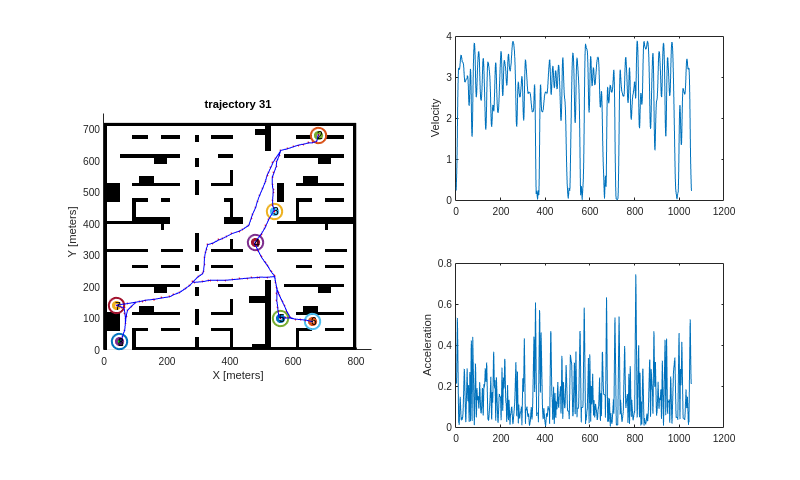


trajectory = get_trajectory(trajectory_tb, 15); %randi(height(trajectory_tb)));


f1 = figure(1); clf;
f1.Position = [1 1 1000 600];
subplot(2,2, [1; 3]);

hold on;
show(map);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'Markersize', 15, 'LineWidth', 2, 'DisplayName', sprintf("p%d", i)); 
end
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(trajectory.path)-1
    plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
text(trajectory.waypoints(:,1)-5, trajectory.waypoints(:,2), string(1:numel(trajectory.waypoints(:,1))));
%plot(current_location(1), current_location(2), 'x', 'MarkerFaceColor', 'red', 'markersize', 17, 'LineWidth', 5, 'DisplayName', sprintf("p%d", i)); 
axis([0 850 0 750])

title(sprintf("trajectory %d", trajectory.id));
hold off;

subplot(2,2,2);
title("velocity profile")
plot(trajectory.velocity_profile(3,:));
ylabel('Velocity');

subplot(2,2,4);
title("acceleration profile")
plot(trajectory.acceleration_profile(3,:));
ylabel('Acceleration');


sim_params.initial_conditions  = load('params/initial_conditions.mat').IC;
sim_params.initial_conditions.Psi = pi/2;
sim_params.initial_conditions.Z = .05;

sim_params.initial_conditions.X = trajectory.start(1);
sim_params.initial_conditions.Y = trajectory.start(2);

% stop measure on the simulation, in general it should stop before this
sim_params.max_sim_time = 3000;

% performance thresholds %%%% max_pos_err calculation is incorrect (does
% not account for time offset, needs updated)
sim_params.perf_param_thresh.max_pos_err  = 8; % this is check in the simulation
sim_params.perf_param_thresh.min_soc      = .15; % this is check in the simulation
sim_params.perf_param_thresh.min_v        = 19.5; % this is checked in the simulation
sim_params.perf_param_thresh.min_soh_batt = 18; % this is checked after %% can this even be done?
sim_params.perf_param_thresh.avg_pos_err  = 3.0; % this is checked after
sim_params.perf_param_thresh.max_pos_err_var  = 3.0; % check this (currently not used)
% sim_params.z_ref = 8;


% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;

sim_params.z_ref = sim_params.initial_conditions.z_ref;

sim_params.battery_estimator   = load('estimation/batteryestimator').batteryestimator;
sim_params.battery_estimator.Qinit = uav.battery.Q;

if strcmp(uav.uav.common_name, 'default')
    sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
    sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;
end

process_type = 'degradation';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES));
%%%%% get the battery degradation functions
for i = 1:length(uav.battery.process_id)
    params = process_tb(process_tb.id_1 == uav.battery.process_id(i), 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.battery.(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end
%%%%% get the motor degradation function
for j = 1:length(uav.motors)
    params = process_tb(process_tb.id_1 == uav.motors(j).process_id(1), 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.motors(j).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end
%%%%% get the esc failure probability function
process_type = 'failure probability';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES));
for j = 1:length(uav.escs)
    params = process_tb(process_tb.id_1 == uav.escs(j).process_id, 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.escs(j).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end

process_type = 'environment';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))  ;
i = randi(height(process_tb));
params = process_tb(i, 'parameters').parameters{1};
res = jsondecode(string(params));
fn = fieldnames(res);
for j = 1:length(fn)
    processes.(sprintf("%s", process_type)).(sprintf("%s", process_tb(i, 'subtype').subtype{1})).(sprintf("%s", process_tb(i, 'subtype2').subtype2{1})).(sprintf("%s", fn{j})) = res.(fn{j});
end

clear('description', 'i', 'params', 'j', 'proc_tb', 'process_tb', 'process_type', 'res', 'fn');

P_failure = zeros(length(uav.escs), 1);


age = 1500;

Q_mu = polyval(uav.battery.q_coef, age);
Q_std = .02*Q_mu;

R0_mu = polyval(uav.battery.r_coef, age);
R0_std = .02*R0_mu;

uav.battery.Q = normrnd(Q_mu, Q_std);
uav.battery.Q = min(22.5, uav.battery.Q);
disp(uav.battery.Q);

uav.battery.R0 = normrnd(R0_mu, R0_std);
uav.battery.R0 = max(.00105, uav.battery.R0);
disp(uav.battery.R0)

for i = 1:length(uav.motors)
    m_mu = polyval(uav.motors(i).r_coef, age);
    m_std = .02*m_mu;
    uav.motors(i).Req = normrnd(m_mu, m_std);
    % min bound on motor resistance
    uav.motors(i).Req = max(.265, uav.motors(i).Req);
    uav.motors(i).Req = min(.275, uav.motors(i).Req);
    disp(uav.motors(i).Req)
end




tic
sim(sprintf('simulink/uav_simulation_tarot%d.slx', row));

Program interruption (Ctrl-C) has been detected.

toc

z_start = battery.battery_true.z.Data(1);
z_end = battery.battery_true.z.Data(end);
v_start = battery.battery_true.v.Data(1);
v_end = battery.battery_true.v.Data(end);

uav.battery.v = v_end;
uav.battery.z = z_end;

dt_stop = dt_start + minutes(time.Data(end, 1));

stop_code = max(find(any(stop_codes.Data(:,:))));


disp('checking constraints')
if mean(errors.euclidean_pos_err.Data) > sim_params.perf_param_thresh.avg_pos_err
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'average position error'));
    disp('position error violation');
end

if  uav.battery.Q < sim_params.perf_param_thresh.min_soh_batt
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'low soh (battery)'));
    disp('low charge capacitance, no longer safe to fly');
end  

if stop_code ~= 4
    fprintf("Threshold violation or failure indicated by stop_code %d\n", stop_code);

    fid = fopen('fail.txt', 'a+');
    fprintf(fid, '1');
    fclose(fid);

end



rng('shuffle');
rand_num = randi(9999999);
rng(rand_num);
disp(rand_num);

      639667




s = dbstack();
row = regexp(s(1).file, '(\d*)', 'match');
row = int32(str2double(row{1}));
row = 2;
disp(row)

     2





% disp('initializing workspace');
% % get the root directory
% file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), filesep);
% idx = find(strcmp(file_path, 'uavtestbed'));
% root_directory = strjoin(file_path(1:idx), filesep);
% % switch to the root directory

username = char(java.lang.System.getProperty('user.name'));

root_directory = sprintf('/home/%s/uavtestbed', username);

cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% load the api
api = jsondecode(fileread('sql/api.json'));

% username=input('username: ', 's');
% password=input('password: ', 's');

password = 'Ch0colate!';
db_name = 'uav2_db';

%the database connection
conn = database(db_name, username, password);
disp(conn)

  connection with properties:

                  DataSource: 'uav2_db'
                    UserName: 'macslab'
                      Driver: 'org.postgresql.Driver'
                         URL: 'jdbc:postgresql://localho ...'
                     Message: ''
                        Type: 'JDBC Connection Object'
  Database Properties:

                  AutoCommit: 'on'
                    ReadOnly: 'off'
                LoginTimeout: 0
      MaxDatabaseConnections: 8192

  Catalog and Schema Information:

              DefaultCatalog: 'uav2_db'
                    Catalogs: {'uav2_db'}
                     Schemas: {'information_schema', 'pg_catalog', 'public'}

  Database and Driver Information:

         DatabaseProductName: 'PostgreSQL'
      DatabaseProductVersion: '14.6 (Ubuntu 14.6-1.pgdg2 ...'
                  DriverName: 'PostgreSQL JDBC Driver'
               DriverVersion: '42.4.0'




stop_code_tb = select(conn, "select * from stop_code_tb;");

experiment_info = "testing new updates";

group_id = select(conn, sprintf("select id from group_tb where info ilike '%%%s%%';", experiment_info)).id;
if isempty(group_id)
    execute(conn, sprintf('insert into group_tb("info") values(''%s'')', experiment_info));
    group_id = select(conn, sprintf("select id from group_tb where info ilike '%%%s%%';", experiment_info)).id;
end

disp('loading uav');

loading uav



% check out what UAVs are in the db
uav_tb = select(conn, api.matlab.assets.LOAD_ALL_UAVS);
uav_tb = sortrows(uav_tb, {'id', 'version'});


% serial_number = char(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).serial_number);
% serial_number = string(serial_number(1,:));
% version = max(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).version);
% uav = load_uav(conn, serial_number, version, api);

uav = uav_tb(row,:);
uav = load_uav_id(conn, api, uav)

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
               escs: [8×1 struct]
             motors: [8×1 struct]
                gps: [1×1 struct]
    max_flight_time: 25
                 id: 32
            version: 1
               mass: 10.6600
     dynamics_srate: 0.0250



% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from session_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second');
% get the flight_id (the unique id in the data table)
flight_id = table2array(select(conn, 'select id from session_tb order by id desc limit 1;')) + 1;
sprintf('flight_id: %d', flight_id)

ans = 'flight_id: 10'


if isempty(flight_id)
    flight_id = 1;
end

% the flight number of the selected uav (i.e. how many flights it has gone
% previously + 1 for the upcomming flight)
flight_num = table2array(select(conn, sprintf('select flight_num from session_tb where uav_id = %d order by dt_start desc limit 1;', uav.id))) + 1;
if isempty(flight_num)
    flight_num = 1;
end

% load the trajectory information
trajectory_tb = readtable('trajectories/trajectories_exported.csv');
trajectory_tb = trajectory_tb(trajectory_tb.path_time < 1300, :);
trajectory_tb = trajectory_tb(trajectory_tb.path_time > 950, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')

trajectory_tb = 28×13 table
    id    path_distance    path_time    risk_factor         start            destination                                                               x_waypoints                                                                                                                   y_waypoints                                                           x_ref_points    y_ref_points    sample_time    reward       map    
    __    _____________    _________    ___________    ________________    ________________    ____________________________________________________________________________________________________________________________


trajectory = get_trajectory(trajectory_tb, randi(height(trajectory_tb)));
disp(trajectory)

                      id: 41
           path_distance: 2.5447e+03
               path_time: 983.7100
             risk_factor: 0.0100
                   start: [440 50]
             destination: [440 50]
            x_ref_points: [1074×2 double]
            y_ref_points: [1074×2 double]
             sample_time: 1
                  reward: 1
                     map: 'bigmap'
               waypoints: [13×2 double]
                    path: [174×2 double]
                velocity: 2.3686
             flight_time: 17.9053
        velocity_profile: [3×1074 double]
    acceleration_profile: [3×1074 double]
           arrival_times: [26×1 double]



clear trajectory_tb;

setup_sim_params;

load_process_data;


% initialize the degradation parameters to randomly sampled values
   %[TODO] implement estimators and pull covariance 
Q_mu = polyval(uav.battery.q_coef, uav.battery.age);
Q_std = .02*Q_mu;

R0_mu = polyval(uav.battery.r_coef, uav.battery.age);
R0_std = .02*R0_mu;

uav.battery.Q = normrnd(Q_mu, Q_std);
uav.battery.Q = min(22.5, uav.battery.Q);

uav.battery.R0 = normrnd(R0_mu, R0_std);
uav.battery.R0 = max(.00105, uav.battery.R0);

%the battery never charges to the same output voltage level
uav.battery.v = pearsrnd(uav.battery.v-.25, uav.battery.v*.01, -1, 12);
uav.battery.z = min(1.01, pearsrnd(uav.battery.z-.0025, uav.battery.z*.01, -1, 12));

for i = 1:length(uav.motors)
    m_mu = polyval(uav.motors(i).r_coef, uav.motors(i).age);
    m_std = .02*m_mu;
    uav.motors(i).Req = normrnd(m_mu, m_std);
     % min bound on motor resistance
    uav.motors(i).Req = max(.265, uav.motors(i).Req) + normrnd(.002, .001);
    if uav.motors(i).age < 800 
        uav.motors(i).Req = min(.28, uav.motors(i).Req + normrnd(.002, .001));
    elseif uav.motors(i).age >=800 && uav.motors(i).age < 1200
        uav.motors(i).Req = min(.31, uav.motors(i).Req + normrnd(.002, .001));
    end
end


stop_count = 0;
k = 1;
t1 = tic

t1 = uint64
1675282662195629

while stop_count < 5


    %% set constant wind
    rng(round(rand*1000000));
    constant_x_wind = normrnd(2, 1.5);
    if rand > .5
        constant_x_wind = -constant_x_wind;
    end
    constant_y_wind = normrnd(2, 1.5);
    if rand > .5
        constant_y_wind = -constant_y_wind;
    end
    constant_z_wind = normrnd(0, .5);
    if rand > .5
        constant_z_wind = -constant_z_wind;
    end


    disp('sim true');
    sim('simulink/uav_simulation_tarot2.slx');


    z_start = battery.battery_true.z.Data(1);
    z_end = battery.battery_true.z.Data(end);
    v_start = battery.battery_true.v.Data(1);
    v_end = battery.battery_true.v.Data(end);

    uav.battery.v = v_end;
    uav.battery.z = z_end;

    dt_stop = dt_start + minutes(time.Data(end, 1));

    stop_code = max(find(any(stop_codes.Data(:,:))));


    disp('checking constraints')
    if mean(errors.euclidean_pos_err.Data) > sim_params.perf_param_thresh.avg_pos_err
        stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'average position error'));
        disp('position error violation');
    end

    if  uav.battery.Q < sim_params.perf_param_thresh.min_soh_batt
        stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'low soh (battery)'));
        disp('low charge capacitance, no longer safe to fly');
    end  

    if stop_code ~= 4
        fprintf("Threshold violation or failure indicated by stop_code %d\n", stop_code);
        stop_count = stop_count + 1;
        
    end


    disp('charge battery');
    charge_battery;

    disp('update component degradation');
    update_component_degradation;

    disp('update component degradation parameters');
    update_component_parameters;

    disp('update asset age');
    update_assets_age;

    disp('insert flight data');
    insert_flight_data;

    execute(conn, sprintf('insert into true_age_tb ("flight_id", "stop_code", "trajectory_id", "uav_age", "battery_age", "m1_age","m2_age","m3_age","m4_age","m5_age","m6_age","m7_age","m8_age") values (%d, %d, %d, %f, %f, %f, %f, %f, %f, %f, %f, %f, %f);', ...
        flight_id, stop_code, trajectory.id, uav.uav.age, uav.battery.age, uav.motors(1).age, uav.motors(2).age, uav.motors(3).age, uav.motors(4).age, uav.motors(5).age, uav.motors(6).age, uav.motors(7).age, uav.motors(8).age));

    dt_start = dt_stop + minutes(120);
    flight_id = flight_id + 1;
    flight_num = flight_num + 1;
    
    k = k + 1;
%     if k == 3
%         break;
%     end
    break;

end

sim true


checking constraints


charge battery


update component degradation


update component degradation parameters


update asset age


insert flight data



t2 = tic

t2 = uint64
1675282850366198


fprintf("elapsed time: %f", (double(t2 - t1)/10000000.0))

elapsed time: 18.817057


close(conn);
conn.close();
clear conn;



uav_tb = select(conn, api.matlab.assets.LOAD_ALL_UAVS);
uav_tb = sortrows(uav_tb, {'id', 'version'})

uav_tb = 102×20 table
     age      serial_number       common_name       id     version    airframe_id    battery_id                motors_id                             escs_id                 m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    gps_id    max_flight_time    dynamics_srate
    ______    _____________    _________________    ___    _______    ___________    __________    _________________________________    _________________________________    _____ 

uav_id = 492;

uav = uav_tb(uav_tb.id==uav_id, :)

uav = 1×20 table
     age      serial_number       common_name       id     version    airframe_id    battery_id                motors_id                             escs_id                 m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    gps_id    max_flight_time    dynamics_srate
    ______    _____________    _________________    ___    _______    ___________    __________    _________________________________    _________________________________    _____    <s

uav = load_uav_id(conn, api, uav)

battery_tb = 1×31 table
    id     version       owner       type_id               process_id                serial_number       common_name        age      age2    eol         units          units2      id_1    version_1    cycles      Q         G         M         M0       RC          R            R0         n        EOD     z    Ir    h     v       v0     dt                 soc_ocv              
    ___    _______    _______

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
               escs: [8×1 struct]
             motors: [8×1 struct]
                gps: [1×1 struct]
    max_flight_time: 25
                 id: 492
            version: 1
               mass: 10.6600
     dynamics_srate: 0.0250


uav.battery

ans = struct with fields:
               id: 474
          version: 1
            owner: 'macslab'
          type_id: 2
       process_id: [359 295]
    serial_number: '608BFC'
      common_name: 'tarot battery'
              age: 83.2207
             age2: 0
              eol: 7000
            units: 'amp-hours'
           units2: ''
             id_1: 474
        version_1: 1
           cycles: 0
                Q: 22.4379
                G: 163.4413
                M: 0.0092
               M0: 0.0019
               RC: 14.2500
                R: 2.8283e-04
               R0: 0.0021
                n: 0.9987
              EOD: 17.0100
                z: 1
               Ir: 0
                h: 0
                v: 22.2000
               v0: 22.2000
               dt: 1
           z_coef: [1.5088e-11 3.8581e-09 -2.0192e-06 2.7747e-04 -0.0175 0.5278 15.0000]


Q_mu = polyval(uav.battery.q_coef, uav.battery.age)

Unrecognized field name "q_coef".


uav_id = 512;

uav = uav_tb(uav_tb.id==uav_id, :)
uav = load_uav_id(conn, api, uav)
uav.battery

